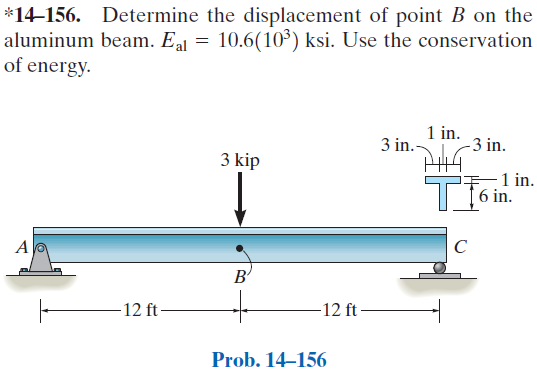

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-156RP-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-156RP-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('concentrated', 'force', -3*u.kip, 12*u.ft);
b = b.add('reaction', 'force', 'Rc', 24*u.ft);
b.E = rewrite(10.6e3*u.ksi,  [u.kip u.ft^2]);
b.L = 24*u.ft;

# section properties

yc = [6/2, 6+1/2]*u.in;
Ac = [1*6, (3+1+3)*1]*u.in^2;
Ic = [1*6^3, (3+1+3)*1^3]/sym(12)*u.in^4;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{702\,x\,\left(432\,{\mathrm{ft}}^{2}-x^{2}\right)}{12021725}\,\frac{1}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 12\,\mathrm{ft}\\ -\frac{702\,\left(x-24\,\mathrm{ft}\right)\,\left(x^{2}-48\,x\,\mathrm{ft}+144\,{\mathrm{ft}}^{2}\right)}{12021725}\,\frac{1}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{2106\,\left(x-12\,\mathrm{ft}\right)\,\left(x+12\,\mathrm{ft}\right)}{12021725}\,\frac{1}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 12\,\mathrm{ft}\\ -\frac{2106\,\left(x-12\,\mathrm{ft}\right)\,\left(x-36\,\mathrm{ft}\right)}{12021725}\,\frac{1}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{3\,x}{2}\,\mathrm{kip} & \text{ if }x\leq 12\,\mathrm{ft}\\ -\frac{3\,\left(x-24\,\mathrm{ft}\right)}{2}\,\mathrm{kip} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{3}{2}\,\mathrm{kip} & \text{ if }x\leq 12\,\mathrm{ft}\\ -\frac{3}{2}\,\mathrm{kip} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 1.5\,\mathrm{kip}\\ \mathrm{Rc} & 1.5\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

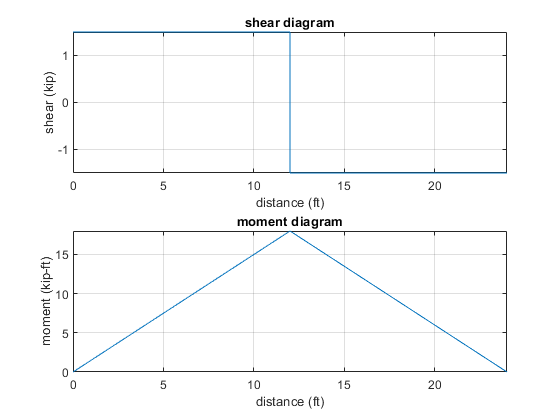

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# displacement at point B

y_B = rewrite(y(b.L/2), u.in);
y_B_vpa = vpa(y_B, 3) %#ok<NASGU> 

$$y\_B\_vpa = -2.42\,\mathrm{in}$$

b.E = rewrite(b.E, u.ksi);
b.I = rewrite(b.I, u.in);

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear y_B_vpa;